# This exercise is to forecast volatility via different methods, campared with actual volatilities measured by high-frequency realised volatility

Out-of-sample forecasts are from 2019-5-20 to 2022-5-19. Rolling estimation window size is 750 and forecast one-day ahead.

The difference between "exercise_VolForecastRV20220807.mlx" is this mlx mix normal and t-distributed innovation. 

The difference between "exercise_VolForecastRV20220805.mlx" is this mlx is for DEBUG, especially for NIKKIE in "exercise_VolForecastRV20220805.mlx" performs super badly, especially CP-RSGARCH and CP-RSGARCH-I. We separate GARCH, GJR, RSGARCH and HAR into different functions to calculate corresponding volatility, VolFcst_GARCH, VolFcst_GJR, VolFcst_RSGARCH and VolFcst_HAR. Then you have to use Save_VolFcst_to_Mat to save results.

clear,clc
addpath("Functions/")

tic
[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('SP500','_20220811','SP500_0608.xlsx',[2021,05,18],'Cluster_Min_Length',100);
toc

Time:  35472 seconds

tic
[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18],'Cluster_Min_Length',80);
toc

tic
[vf_RSGARCHs_1,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,26;2021,05,29],'Cluster_Min_Length',80);
toc

tic
[vf_RSGARCHs_2,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,26;2021,05,29],'Cluster_Min_Length',80);
toc

tic
[vf_RSGARCHs_1,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,05,20],'Cluster_Min_Length',80);
toc

tic
[vf_RSGARCHs_1,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,28;2021,05,30],'Cluster_Min_Length',80);
toc

Index_Name='NIKKIE';
Working_Date='_20220811';
Read_Name='NIKKIE_0608.xlsx';
Time_Outsample=[2021,05,28;2021,05,30];

tic
[vf_RSGARCHs_2,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2022,02,03;2022,02,07],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

toc

Elapsed time is 2481.903448 seconds.


Index_Name='NIKKIE';
Working_Date='_20220811';
Read_Name='NIKKIE_0608.xlsx';
Time_Outsample=[2022,02,03;2022,02,07];

data0805_nikkie=load("results_NORMAL_NIKKIE_size750_20220811/VolFcst_normal_NIKKIE_size750_20220805.mat");

Save_VolFcst_to_Mat('SP500','_20220811','SP500_0608.xlsx',[2021,05,18;2022,05,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',100);
load("VolFcst_NORMAL_SP500_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)
toc

tic
[vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis]=VolFcst_GARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,06,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

[vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR]=VolFcst_GJR('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,06,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

[vf_HARs,insample_fitness_HARs,para_HAR,K_HAR]=VolFcst_HAR('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,06,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,06,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

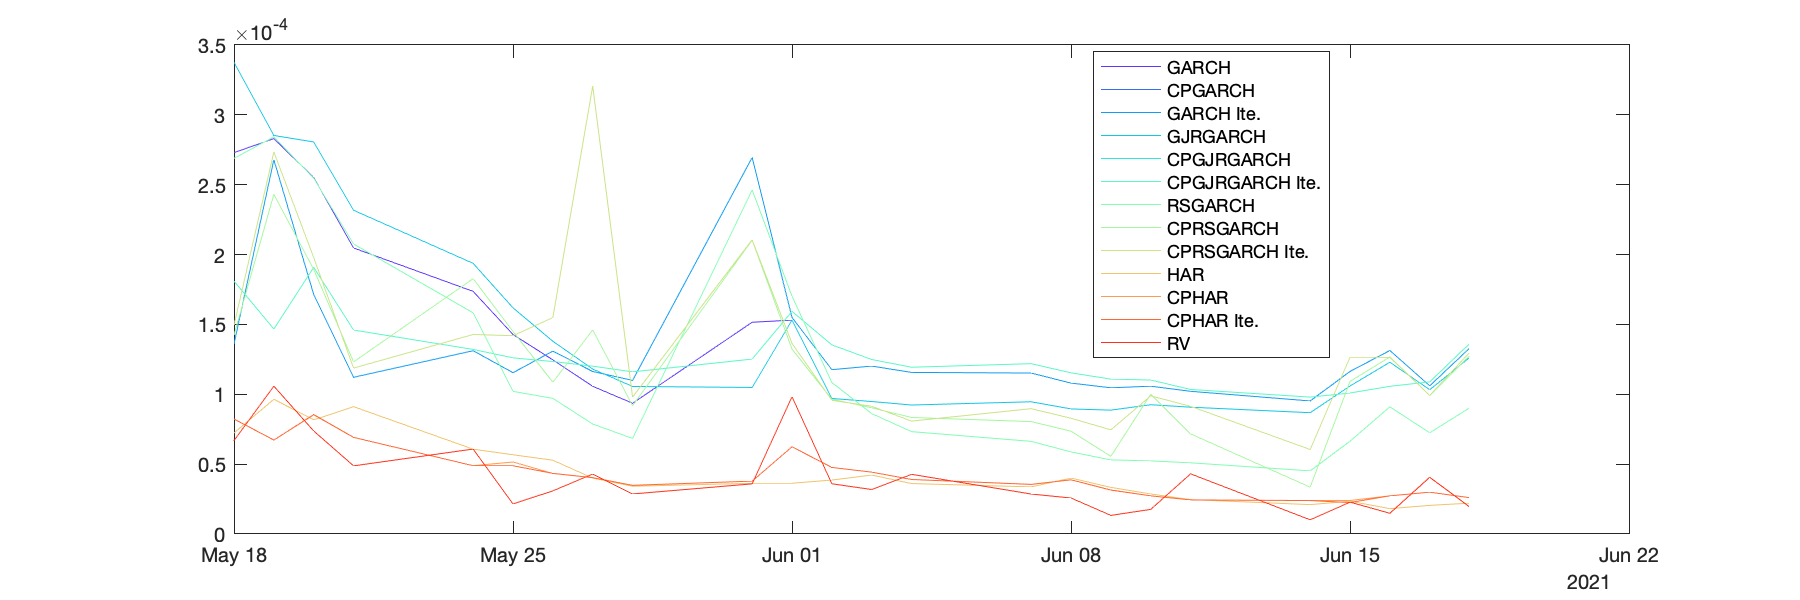

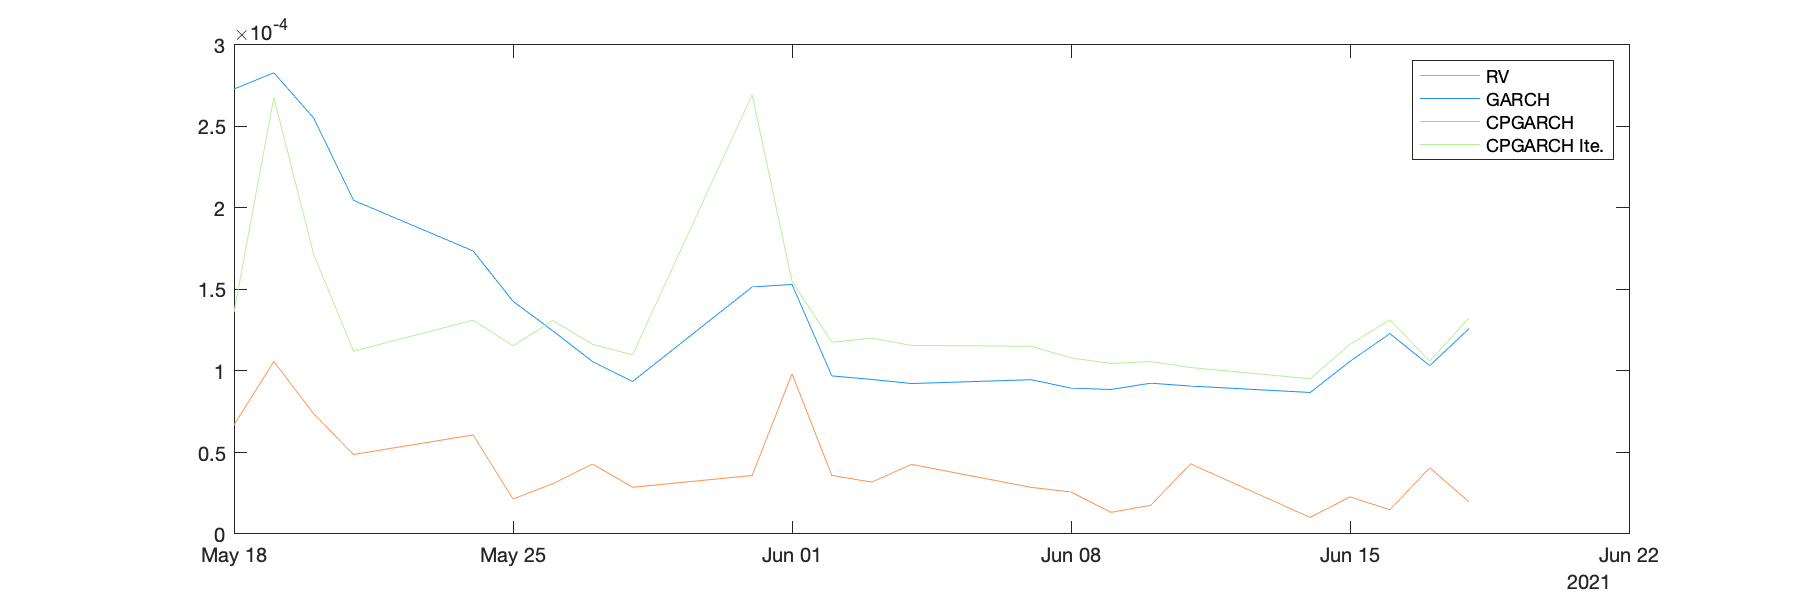

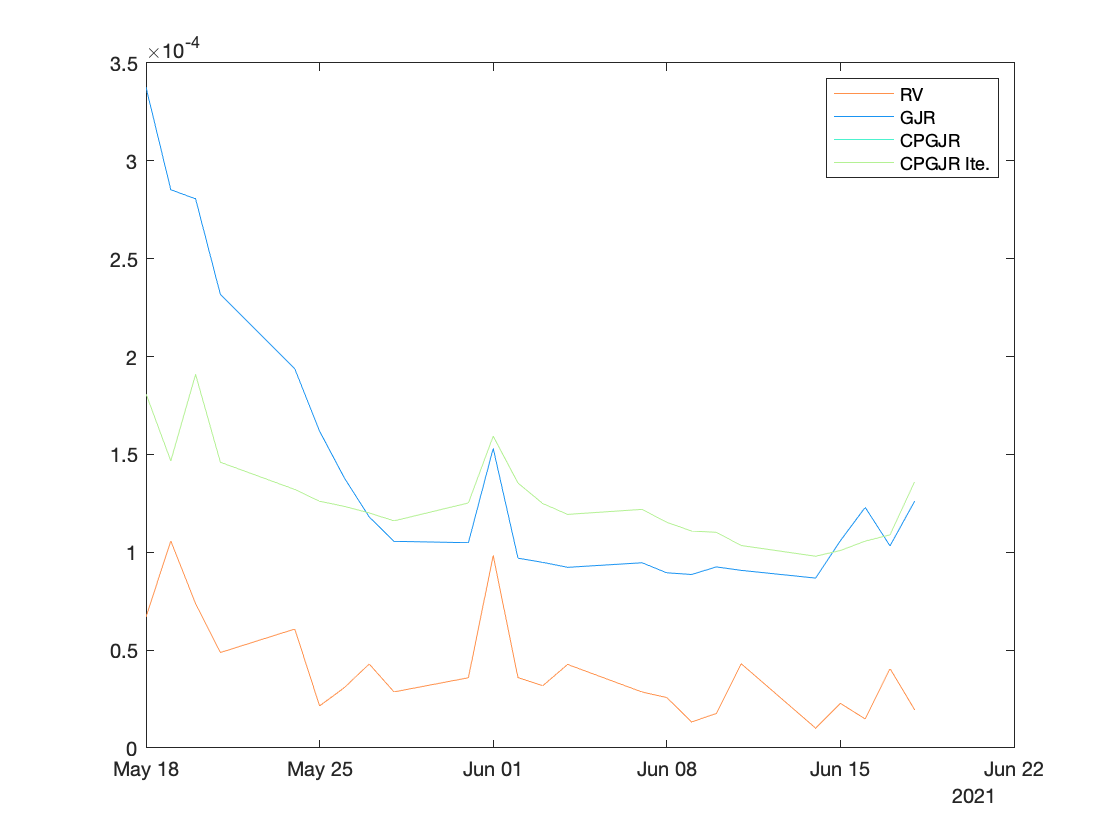

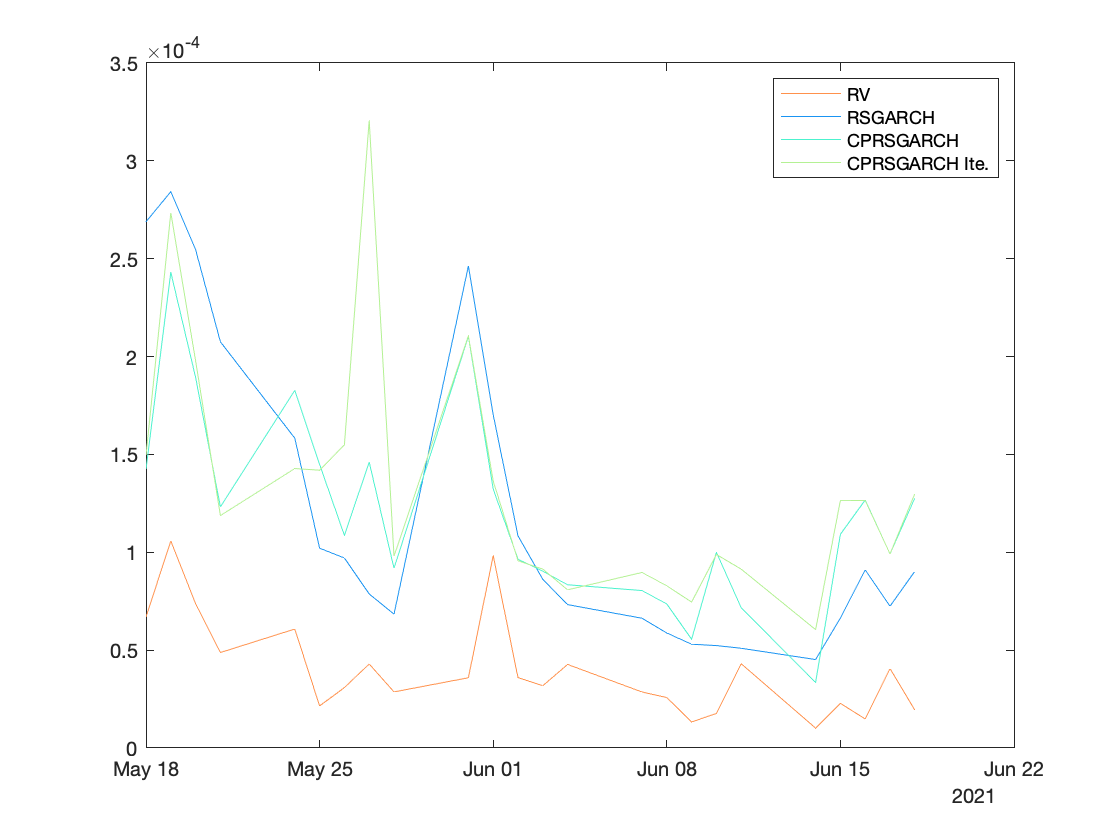

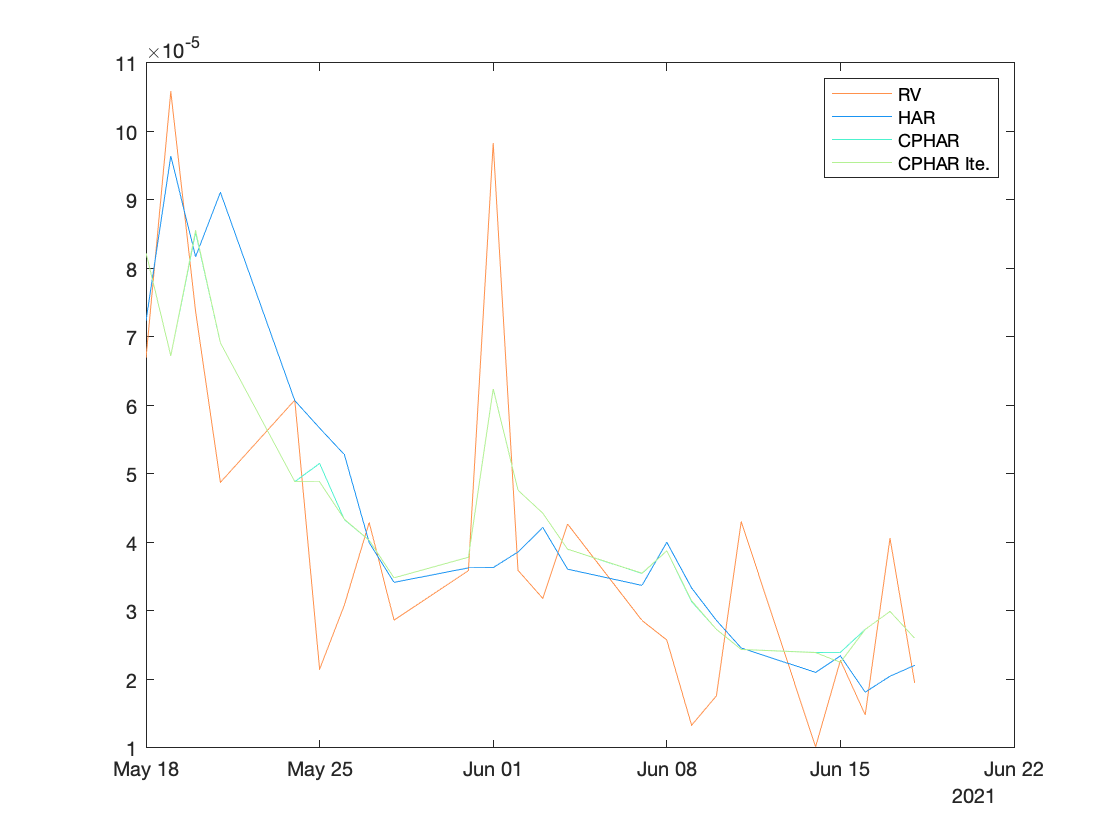

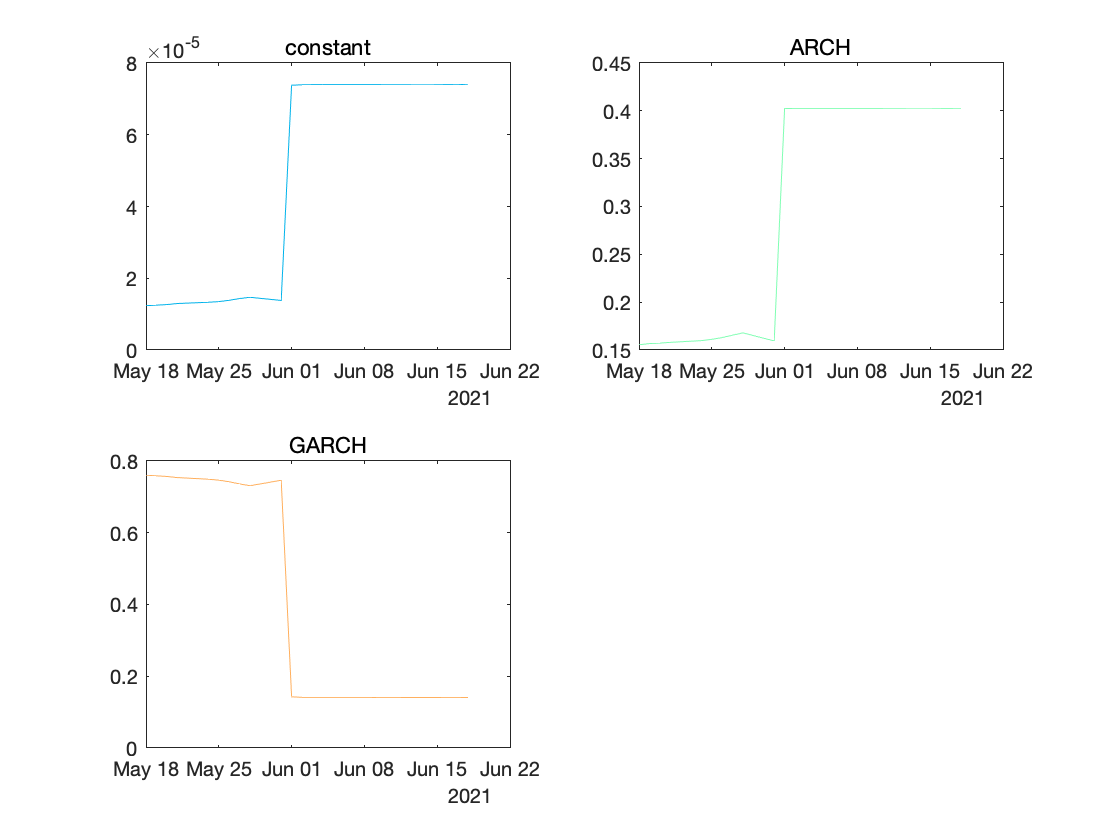

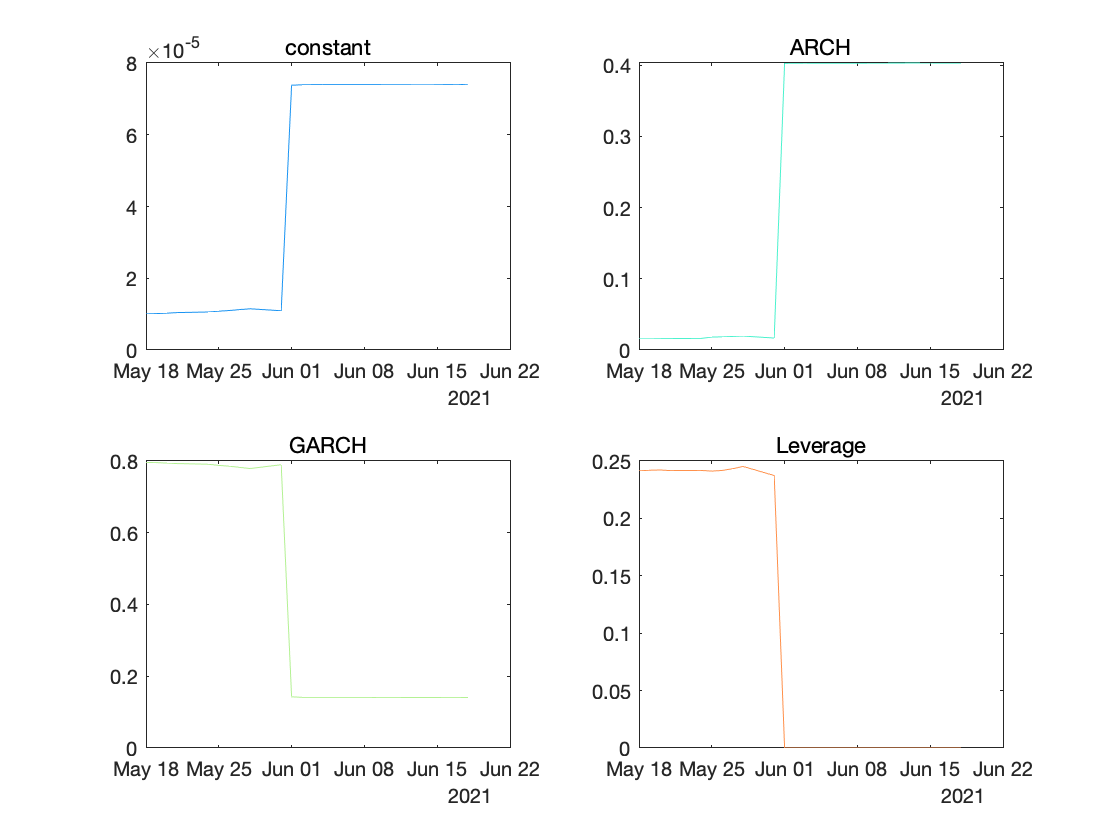

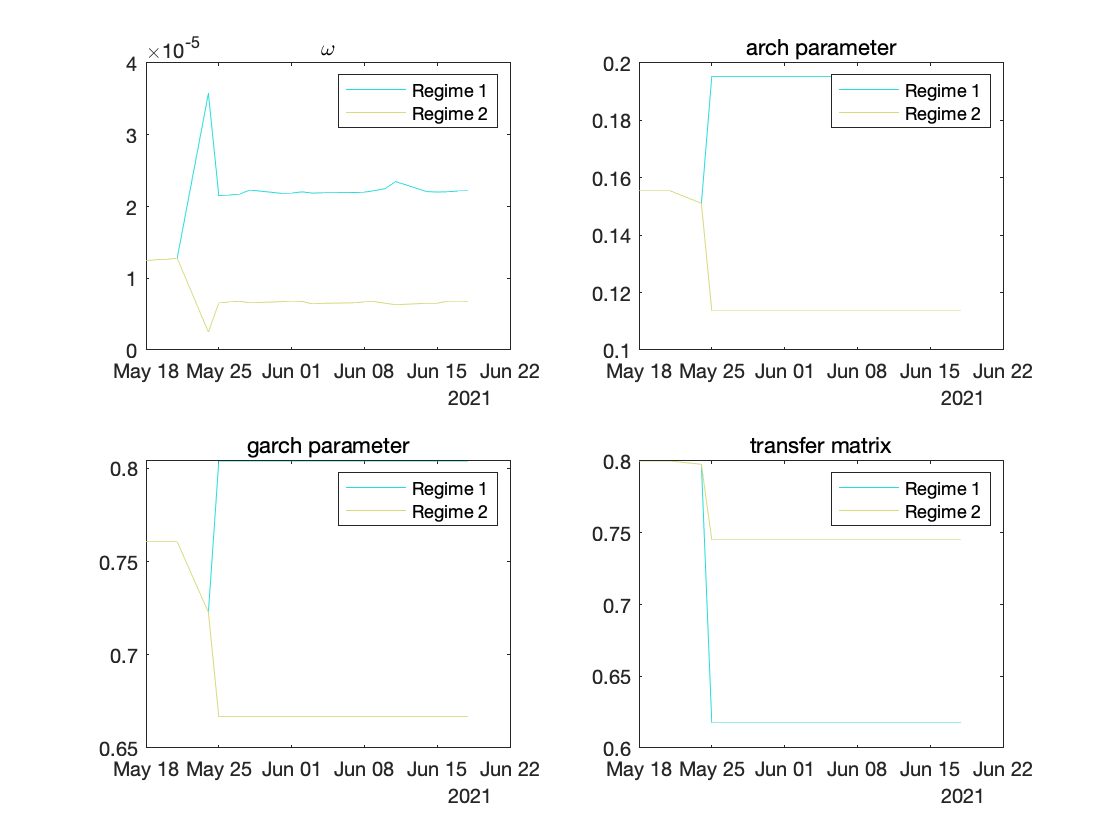

outsample_mae_rmse_allmodel = 12×2 table
                        MAE       RMSE 
                       ______    ______

    GARCH              9.5228    10.484
    CPGARCH            9.2759    9.9708
    GARCH Ite.         9.2759    9.9708
    GJRGARCH           10.146    11.581
    CPGJRGARCH         8.7384    8.9216
    CPGJRGARCH Ite.    8.7384    8.9216
    RSGARCH            7.8755    9.8468
    CPRSGARCH          7.9241    8.7704
    CPRSGARCH Ite.        9.3    10.713
    HAR                1.3309    1.9756
    CPHAR              1.3571    1.6585
    HAR Ite.           1.3442    1.6404


outsample_mae_rmse_exclude_rsgarch = 9×2 table
                        MAE       RMSE 
                       ______    ______

    GARCH              9.5228    10.484
    CPGARCH            9.2759    9.9708
    GARCH Ite.         9.2759    9.9708
    GJRGARCH           10.146    11.581
    CPGJRGARCH         8.7384    8.9216
    CPGJRGARCH Ite.    8.7384    8.9216
    HAR                1.3309    1.9756
    CPHAR              1.3571    1.6585
    HAR Ite.           1.3442    1.6404


dm_test = 11×1 table
                         Var1  
                       ________

    CPGARCH             0.64749
    GARCH Ite.          0.64749
    GJRGARCH           0.045326
    CPGJRGARCH          0.92755
    CPGJRGARCH Ite.     0.92755
    RSGARCH             0.80764
    CPRSGARCH           0.94369
    CPRSGARCH Ite.      0.44854
    HAR                       1
    CPHAR                     1
    HAR Ite.                  1


test_of_actual_forecast = 12×3 table
                       low_bound    upper_bound      R2   
                       _________    ___________    _______

    GARCH               0.18955       0.43393      0.55997
    CPGARCH             0.10948       0.51698      0.31602
    GARCH Ite.          0.10948       0.51698      0.31602
    GJRGARCH            0.13568       0.35639      0.49283
    CPGJRGARCH          0.43759        1.0951      0.51509
    CPGJRGARCH Ite.     0.43759        1.0951      0.51509
    RSGARCH             0.15105       0.34116      0.56718
    CPRSGARCH           0.15747       0.49997      0.41872
    CPRSGARCH Ite.     0.053755       0.35805      0.26365
    HAR                 0.36204        1.

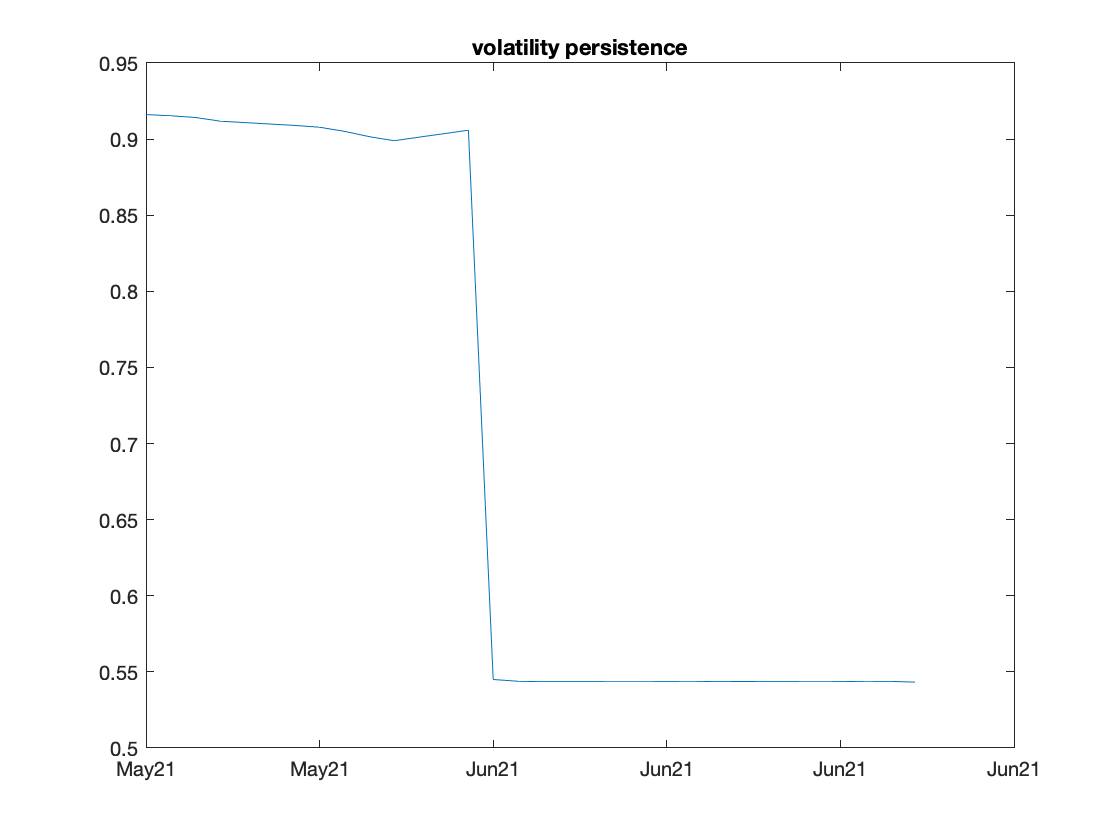

Save_VolFcst_to_Mat('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18;2021,06,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',80);
load("VolFcst_NORMAL_NIKKIE_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)

toc

Elapsed time is 8348.243919 seconds.


tic
[vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis]=VolFcst_GARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18],'Cluster_Min_Length',80);

i1 = 1

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 210

i1 = 211

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

[vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR]=VolFcst_GJR('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 210

i1 = 211

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

[vf_HARs,insample_fitness_HARs,para_HAR,K_HAR]=VolFcst_HAR('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 210

i1 = 211

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18],'Cluster_Min_Length',80);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 210

i1 = 211

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

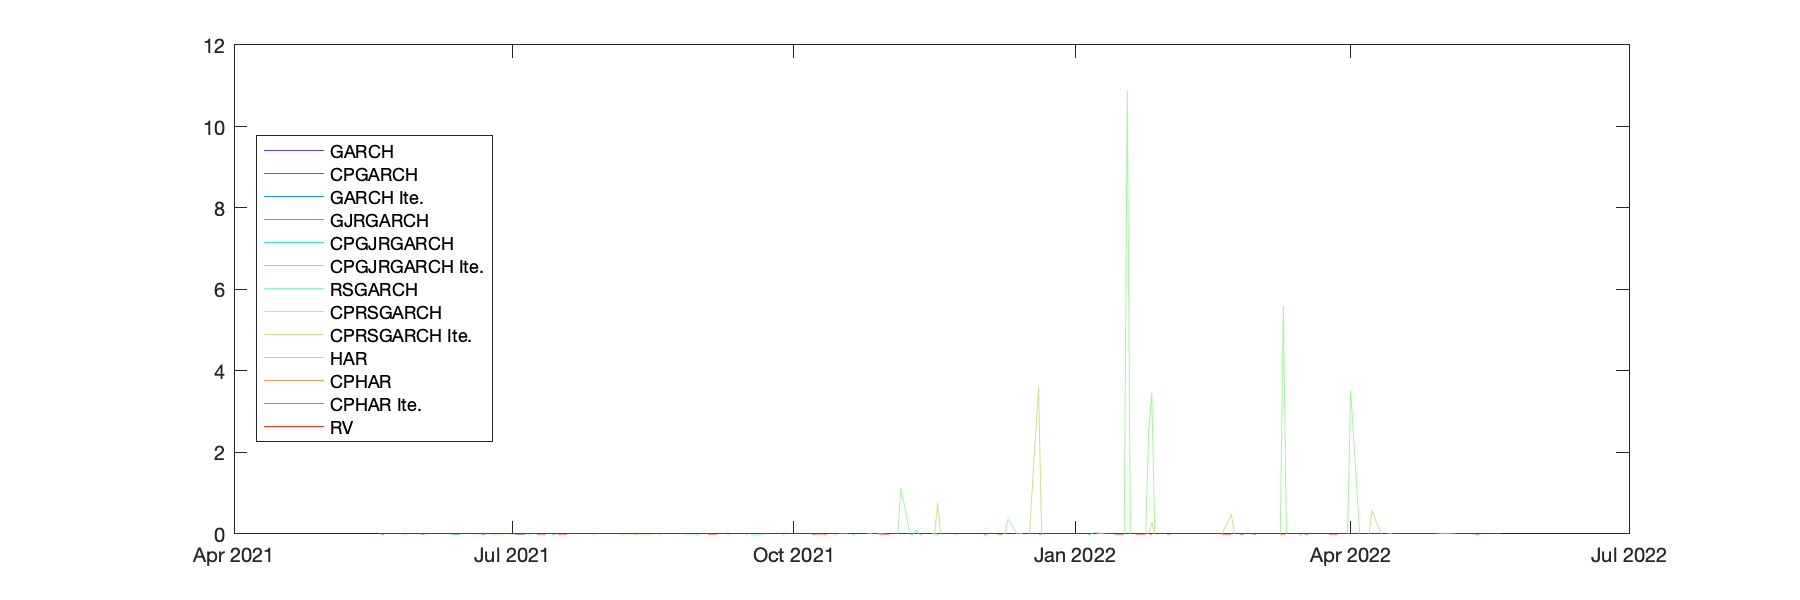

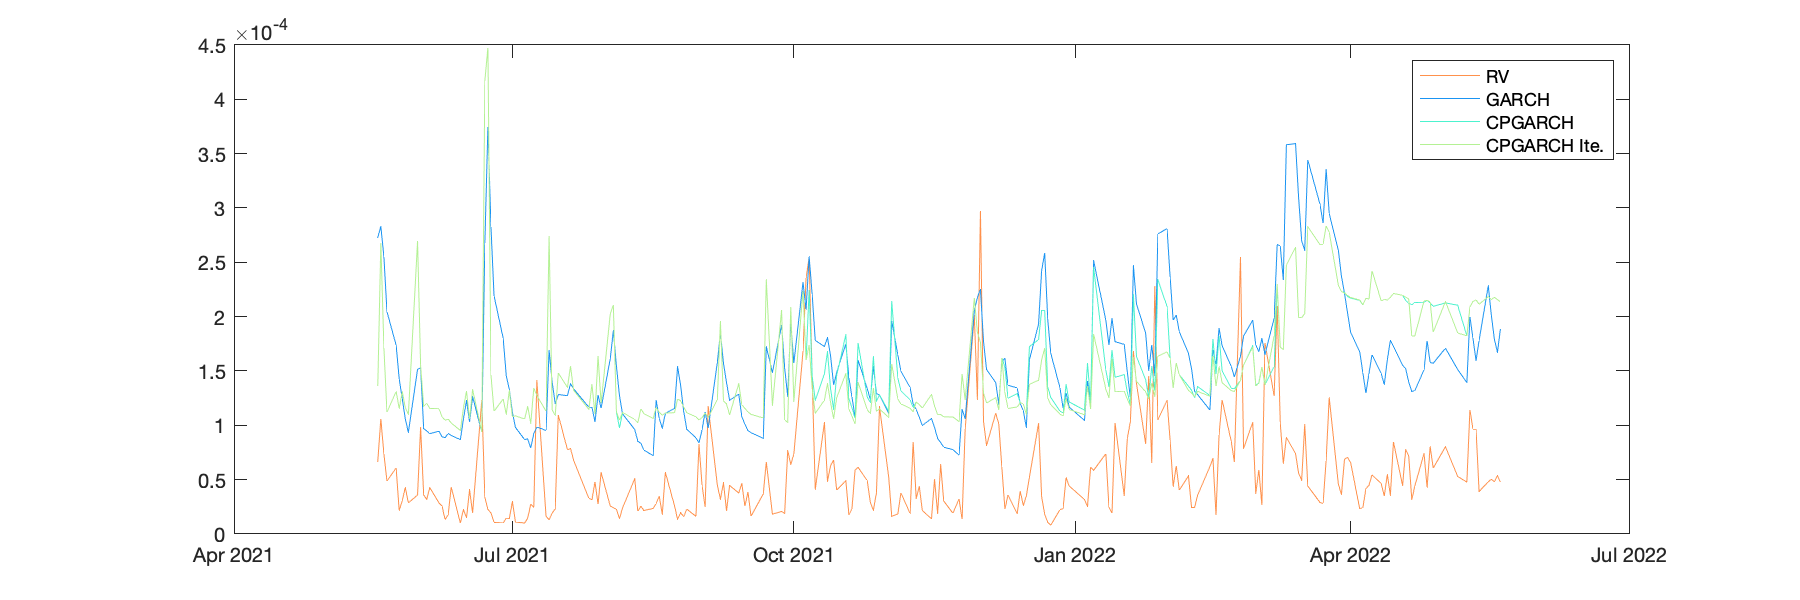

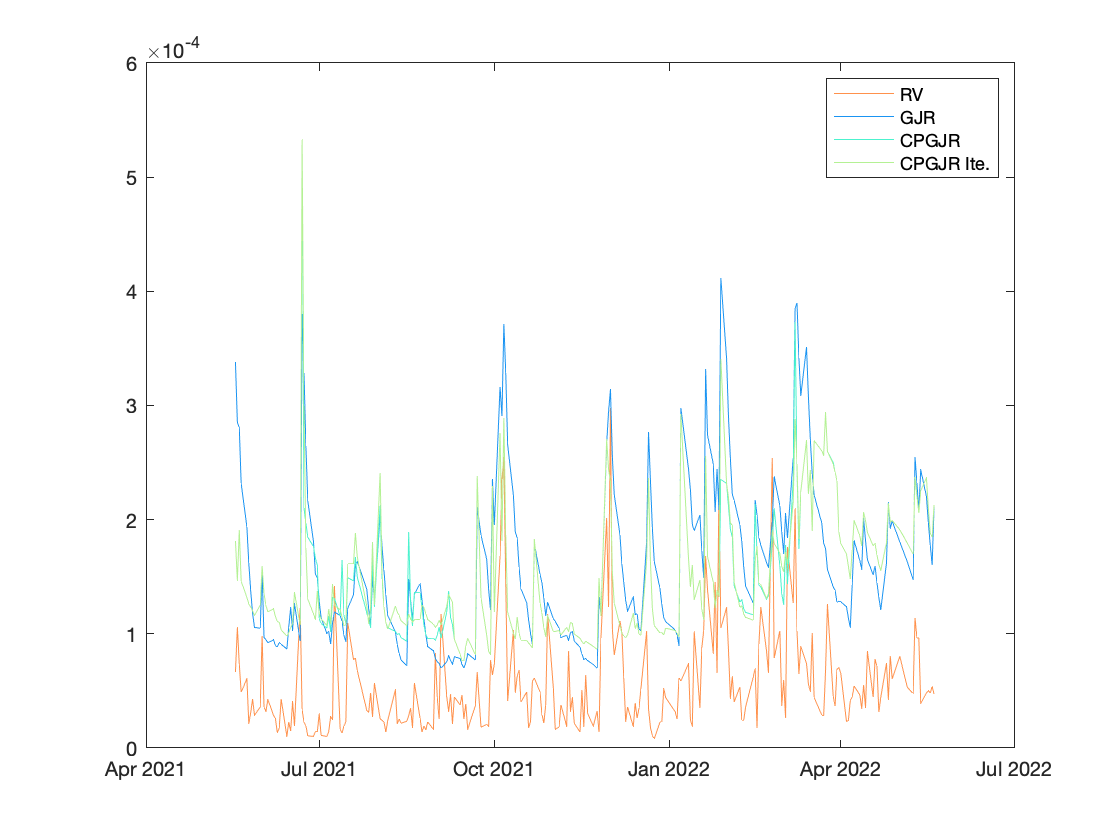

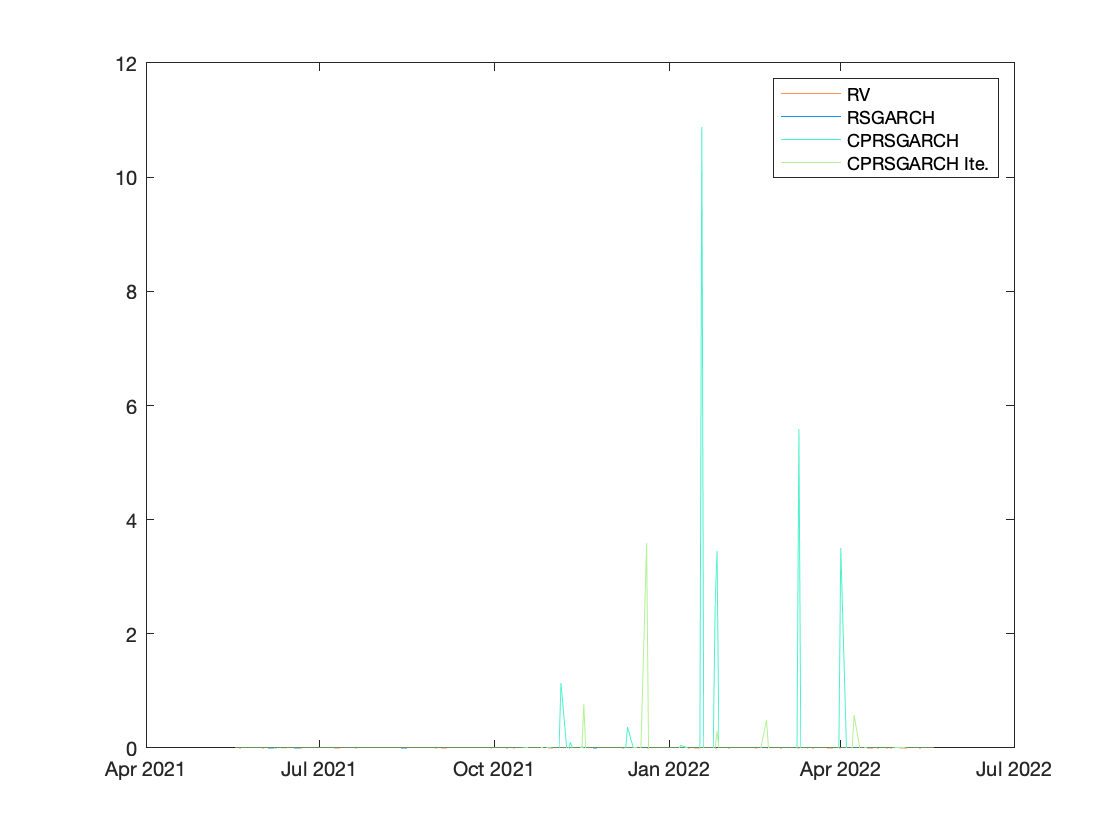

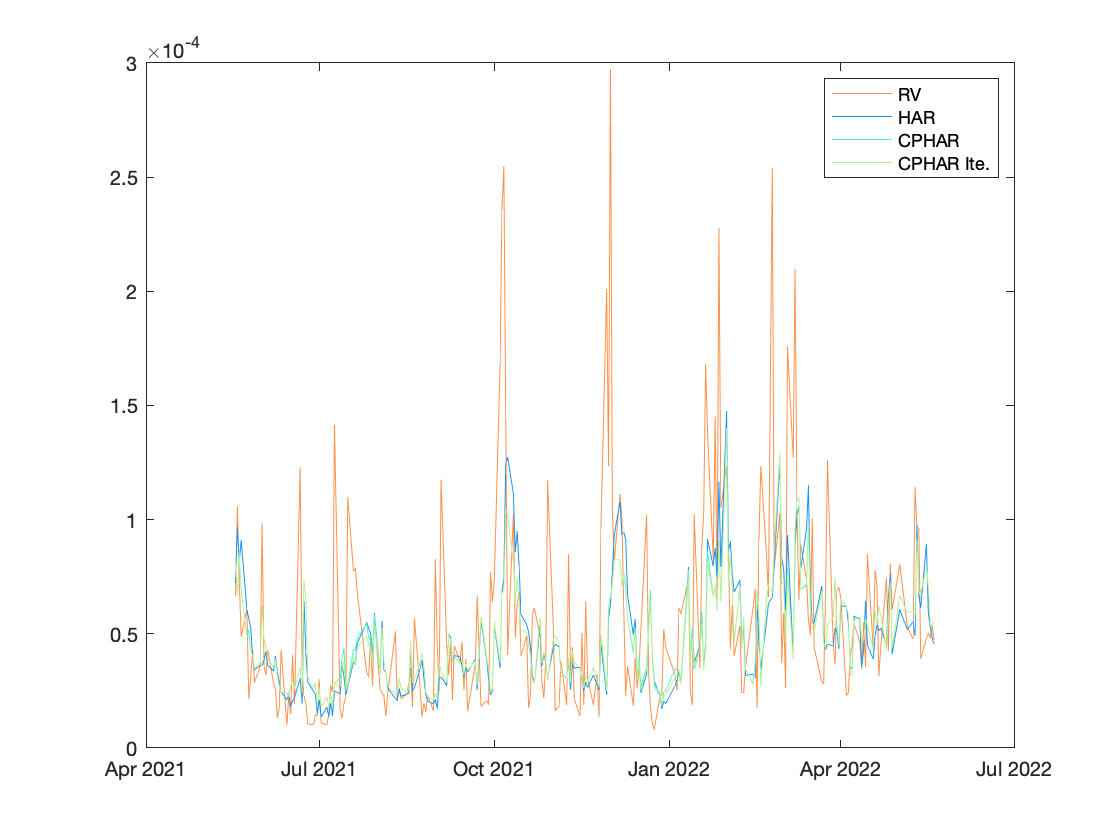

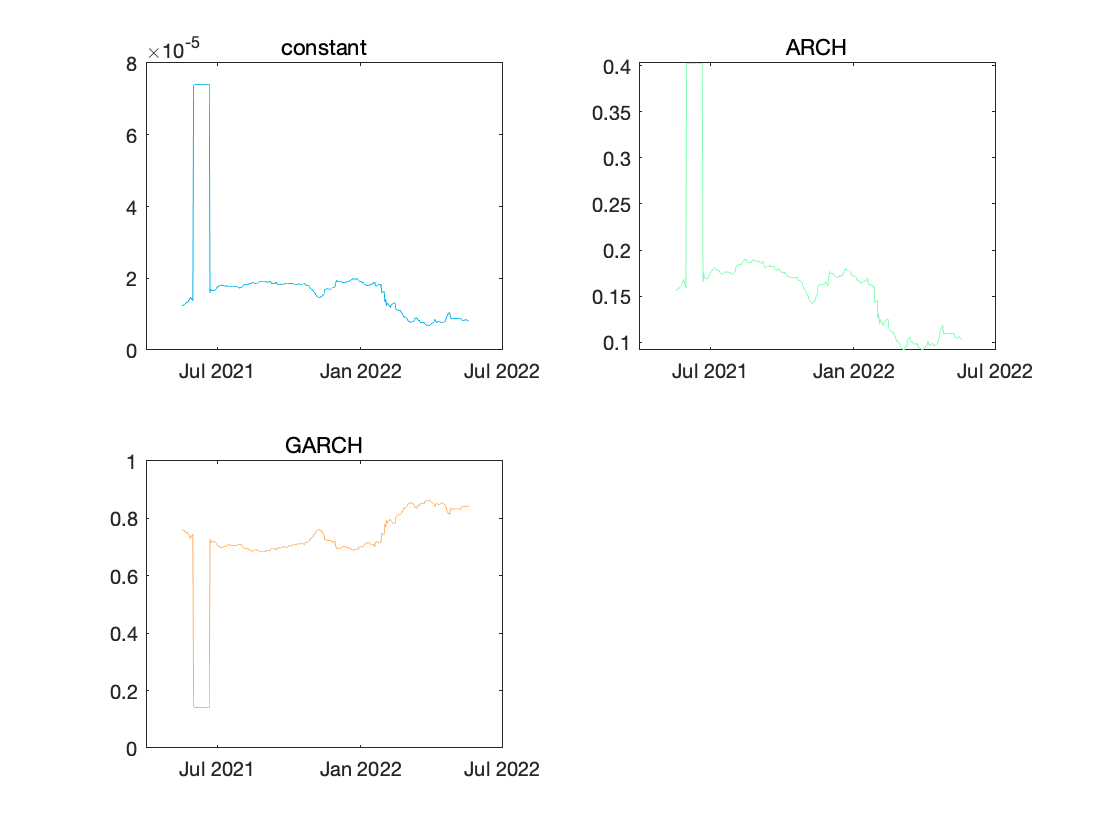

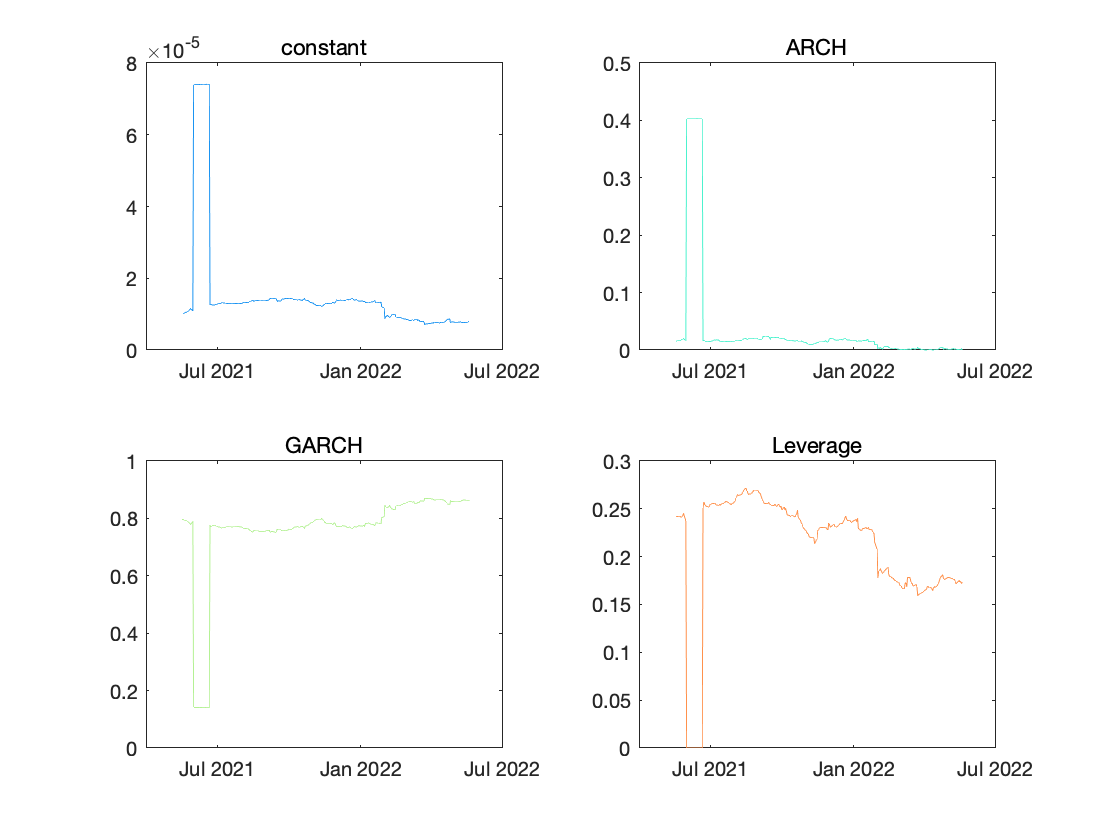

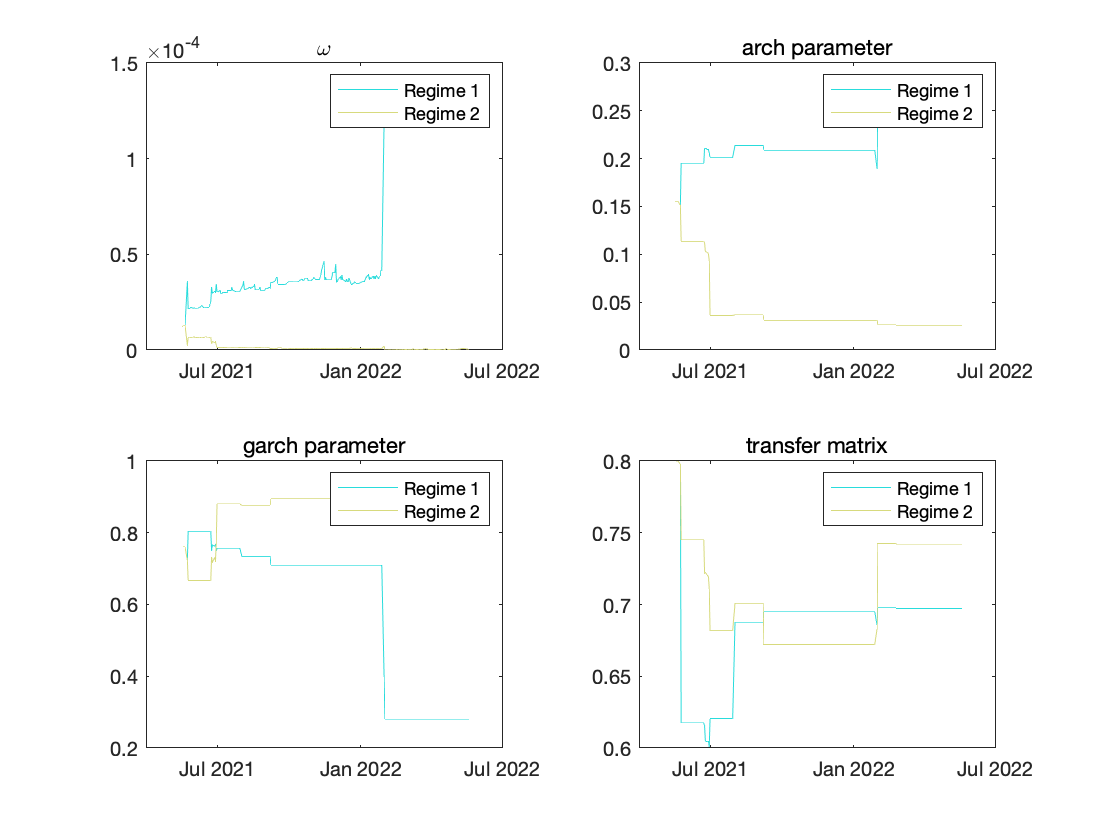

outsample_mae_rmse_allmodel = 12×2 table
                        MAE       RMSE 
                       ______    ______

    GARCH              10.455    11.887
    CPGARCH            10.414    11.806
    GARCH Ite.         9.9818    11.411
    GJRGARCH           10.833    12.441
    CPGJRGARCH         9.5897    11.009
    CPGJRGARCH Ite.    9.6106    11.053
    RSGARCH            11.455    13.525
    CPRSGARCH           11202     85709
    CPRSGARCH Ite.     2342.7     23910
    HAR                2.6943    4.3392
    CPHAR              2.6784    4.2995
    HAR Ite.           2.6717    4.3025


outsample_mae_rmse_exclude_rsgarch = 9×2 table
                        MAE       RMSE 
                       ______    ______

    GARCH              10.455    11.887
    CPGARCH            10.414    11.806
    GARCH Ite.         9.9818    11.411
    GJRGARCH           10.833    12.441
    CPGJRGARCH         9.5897    11.009
    CPGJRGARCH Ite.    9.6106    11.053
    HAR                2.6943    4.3392
    CPHAR              2.6784    4.2995
    HAR Ite.           2.6717    4.3025


dm_test = 11×1 table
                          Var1   
                       __________

    CPGARCH               0.58942
    GARCH Ite.            0.89616
    GJRGARCH             0.060838
    CPGJRGARCH            0.96925
    CPGJRGARCH Ite.       0.96625
    RSGARCH            1.2348e-06
    CPRSGARCH            0.070802
    CPRSGARCH Ite.        0.13681
    HAR                         1
    CPHAR                       1
    HAR Ite.                    1


test_of_actual_forecast = 12×3 table
                        low_bound     upper_bound       R2    
                       ___________    ___________    _________

    GARCH                  0.16175       0.34928       0.10522
    CPGARCH               0.064401       0.27925      0.038936
    GARCH Ite.            0.042724       0.26222      0.029658
    GJRGARCH               0.25472       0.39086       0.26259
    CPGJRGARCH             0.20519       0.38961       0.14143
    CPGJRGARCH Ite.        0.20412       0.38851       0.14058
    RSGARCH                0.14198       0.27976       0.12922
    CPRSGARCH           -3.257e-06    1.0416e-05     0.0043223
    CPRSGARCH Ite.     -1.3801e-05    3.5059e-05     0.0029886
    HA

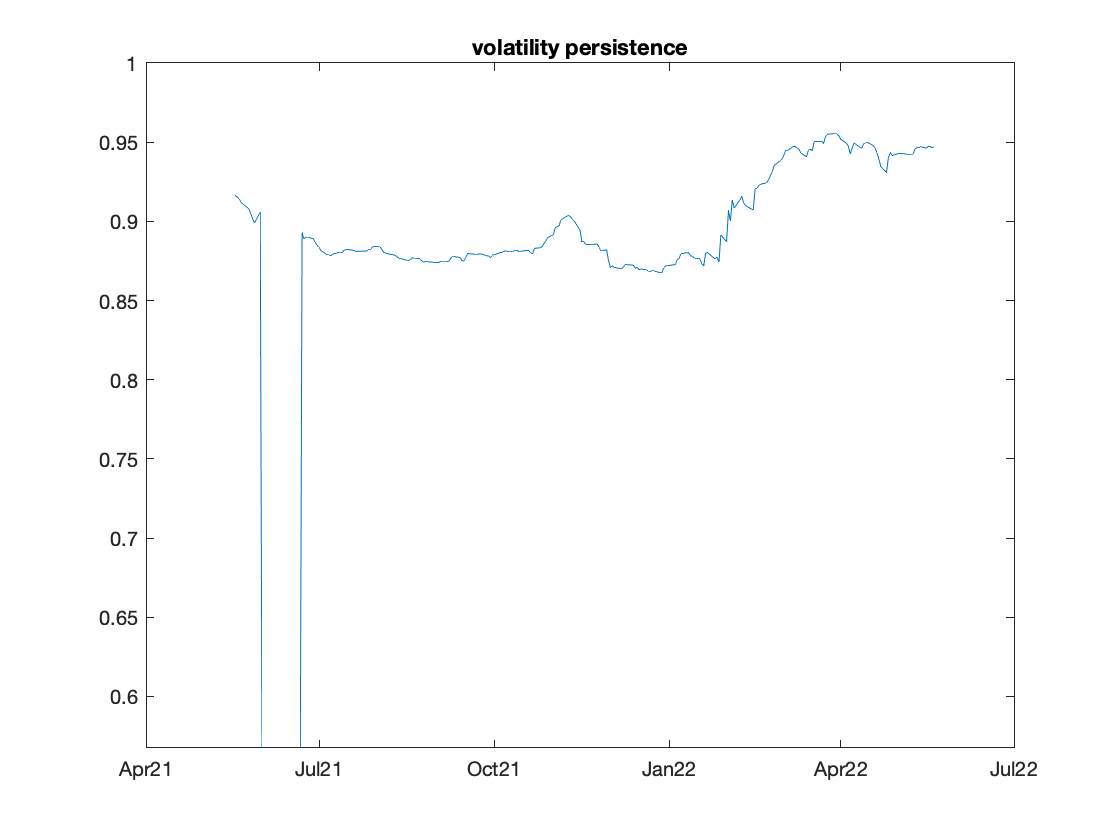

Save_VolFcst_to_Mat('NIKKIE','_20220811','NIKKIE_0608.xlsx',[2021,05,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',80);
load("VolFcst_NORMAL_NIKKIE_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)

toc

Elapsed time is 166164.233460 seconds.


[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2021,05,18],'Cluster_Min_Length',100);

i1 = 1

ans = 1

tic
[vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis]=VolFcst_GARCH('SP500','_20220811','SP500_0608.xlsx',[2021,05,18],'Cluster_Min_Length',100);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 210

i1 = 211

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

i1 = 248

i1 = 249

i1 = 250

i1 = 251

i1 = 252

i1 = 253

i1 = 254

i1 = 255

i1 = 256

i1 = 257

i1 = 258

i1 = 259

[vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR]=VolFcst_GJR('SP500','_20220811','SP500_0608.xlsx',[2021,05,18],'Cluster_Min_Length',100);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

i1 = 82

i1 = 83

i1 = 84

i1 = 85

i1 = 86

i1 = 87

i1 = 88

i1 = 89

i1 = 90

i1 = 91

i1 = 92

i1 = 93

i1 = 94

i1 = 95

i1 = 96

i1 = 97

i1 = 98

i1 = 99

i1 = 100

i1 = 101

i1 = 102

i1 = 103

i1 = 104

i1 = 105

i1 = 106

i1 = 107

i1 = 108

i1 = 109

i1 = 110

i1 = 111

i1 = 112

i1 = 113

i1 = 114

i1 = 115

i1 = 116

i1 = 117

i1 = 118

i1 = 119

i1 = 120

i1 = 121

i1 = 122

i1 = 123

i1 = 124

i1 = 125

i1 = 126

i1 = 127

i1 = 128

i1 = 129

i1 = 130

i1 = 131

i1 = 132

i1 = 133

i1 = 134

i1 = 135

i1 = 136

i1 = 137

i1 = 138

i1 = 139

i1 = 140

i1 = 141

i1 = 142

i1 = 143

i1 = 144

i1 = 145

i1 = 146

i1 = 147

i1 = 148

i1 = 149

i1 = 150

i1 = 151

i1 = 152

i1 = 153

i1 = 154

i1 = 155

i1 = 156

i1 = 157

i1 = 158

i1 = 159

i1 = 160

i1 = 161

i1 = 162

i1 = 163

i1 = 164

i1 = 165

i1 = 166

i1 = 167

i1 = 168

i1 = 169

i1 = 170

i1 = 171

i1 = 172

i1 = 173

i1 = 174

i1 = 175

i1 = 176

i1 = 177

i1 = 178

i1 = 179

i1 = 180

i1 = 181

i1 = 182

i1 = 183

i1 = 184

i1 = 185

i1 = 186

i1 = 187

i1 = 188

i1 = 189

i1 = 190

i1 = 191

i1 = 192

i1 = 193

i1 = 194

i1 = 195

i1 = 196

i1 = 197

i1 = 198

i1 = 199

i1 = 200

i1 = 201

i1 = 202

i1 = 203

i1 = 204

i1 = 205

i1 = 206

i1 = 207

i1 = 208

i1 = 209

i1 = 212

i1 = 213

i1 = 214

i1 = 215

i1 = 216

i1 = 217

i1 = 218

i1 = 219

i1 = 220

i1 = 221

i1 = 222

i1 = 223

i1 = 224

i1 = 225

i1 = 226

i1 = 227

i1 = 228

i1 = 229

i1 = 230

i1 = 231

i1 = 232

i1 = 233

i1 = 234

i1 = 235

i1 = 236

i1 = 237

i1 = 238

i1 = 239

i1 = 240

i1 = 241

i1 = 242

i1 = 243

i1 = 244

i1 = 245

i1 = 246

i1 = 247

i1 = 248

i1 = 249

i1 = 250

i1 = 251

i1 = 252

i1 = 253

i1 = 254

i1 = 255

i1 = 256

i1 = 257

i1 = 258

i1 = 259

[vf_HARs,insample_fitness_HARs,para_HAR,K_HAR]=VolFcst_HAR('SP500','_20220811','SP500_0608.xlsx',[2021,05,18],'Cluster_Min_Length',100);

i1 = 1

i1 = 2

i1 = 3

i1 = 4

i1 = 5

i1 = 6

i1 = 7

i1 = 8

i1 = 9

i1 = 10

i1 = 11

i1 = 12

i1 = 13

i1 = 14

i1 = 15

i1 = 16

i1 = 17

i1 = 18

i1 = 19

i1 = 20

i1 = 21

i1 = 22

i1 = 23

i1 = 24

i1 = 25

i1 = 26

i1 = 27

i1 = 28

i1 = 29

i1 = 30

i1 = 31

i1 = 32

i1 = 33

i1 = 34

i1 = 35

i1 = 36

i1 = 37

i1 = 38

i1 = 39

i1 = 40

i1 = 41

i1 = 42

i1 = 43

i1 = 44

i1 = 45

i1 = 46

i1 = 47

i1 = 48

i1 = 49

i1 = 50

i1 = 51

i1 = 52

i1 = 53

i1 = 54

i1 = 55

i1 = 56

i1 = 57

i1 = 58

i1 = 59

i1 = 60

i1 = 61

i1 = 62

i1 = 63

i1 = 64

i1 = 65

i1 = 66

i1 = 67

i1 = 68

i1 = 69

i1 = 70

i1 = 71

i1 = 72

i1 = 73

i1 = 74

i1 = 75

i1 = 76

i1 = 77

i1 = 78

i1 = 79

i1 = 80

i1 = 81

[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('SP500','_20220811','SP500_0608.xlsx',[2021,05,18],'Cluster_Min_Length',100);
Save_VolFcst_to_Mat('SP500','_20220811','SP500_0608.xlsx',[2021,05,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',100);
load("VolFcst_NORMAL_SP500_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)
toc
tic
[vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis]=VolFcst_GARCH('DAX','_20220811','DAX_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR]=VolFcst_GJR('DAX','_20220811','DAX_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_HARs,insample_fitness_HARs,para_HAR,K_HAR]=VolFcst_HAR('DAX','_20220811','DAX_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('DAX','_20220811','DAX_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
Save_VolFcst_to_Mat('DAX','_20220811','DAX_0608.xlsx',[2021,05,18;2022,05,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',100);
load("VolFcst_NORMAL_DAX_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)
toc
tic
[vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis]=VolFcst_GARCH('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR]=VolFcst_GJR('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_HARs,insample_fitness_HARs,para_HAR,K_HAR]=VolFcst_HAR('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
[vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH]=VolFcst_RSGARCH('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2022,05,18],'Cluster_Min_Length',100);
Save_VolFcst_to_Mat('FTSE','_20220811','FTSE_0608.xlsx',[2021,05,18;2022,05,18], ...
    vf_GARCHs,insample_fitness_GARCHs,para_GARCH,K_GARCH,vol_persis, ...
    vf_GJRs,insample_fitness_GJRs,para_GJR,K_GJR, ...
    vf_HARs,insample_fitness_HARs,para_HAR,K_HAR, ...
    vf_RSGARCHs,insample_fitness_RSGARCHs,para_RSGARCH,K_RSGARCH,transM_RSGARCH,'Cluster_Min_Length',100);
load("VolFcst_NORMAL_FTSE_size750_20220811.mat")
VolFcst__Report(rv,Timeline_outsample,results_folder, ...
    vf_GARCH,vf_CPGARCH,vf_CPGARCHiteration, ...
    vf_GJR,vf_CPGJR,vf_CPGJRiteration, ...
    vf_RSGARCH,vf_CPRSGARCH,vf_CPRSGARCHiteration, ...
    vf_HAR,vf_CPHAR,vf_CPHARiteration, ...
    vol_persis, K_GARCH,K_GJR,K_RSGARCH,K_HAR, ...
    ismae_GARCH,isrmse_GARCH,ismae_CPGARCH,isrmse_CPGARCH,ismae_CPGARCHiteration,isrmse_CPGARCHiteration, ...
    ismae_GJR,isrmse_GJR,ismae_CPGJR,isrmse_CPGJR,ismae_CPGJRiteration,isrmse_CPGJRiteration, ...
    ismae_RSGARCH,isrmse_RSGARCH,ismae_CPRSGARCH,isrmse_CPRSGARCH,ismae_CPRSGARCHiteration,isrmse_CPRSGARCHiteration, ...
    ismae_HAR,isrmse_HAR,ismae_CPHAR,isrmse_CPHAR,ismae_CPHARiteration,isrmse_CPHARiteration, ...
    para_HAR,para_GARCH,para_GJR,para_RSGARCH,transM_RSGARCH)
toc